# 
$$c$$


% i = randperm(10)
% rt = i;
ad = "cv/10c/id.mat";
% gtc = gs;
% save(ad,"gtc","-append") % ir

## 
$$10\times100$$


load(ad, 'c') % for tc

c = 2x10 cell array
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}
    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}    {100x6 table}


c

## 
$$tc!,\text{ random 10$$


load(ad, 'rt') % r10, for nt

rt =      6     1     7     4     9     5     8     3    10     2


% ir(1:5)
% save(ad,'rt',"-append") % ir
% gc = gs;
% save(ad,'gc',"-append") % ir
whos("-file",ad)

  Name      Size                  Bytes  Class     Attributes

  c         2x10                 140240  cell                
  cc        2x10                 812240  cell                
  g         2x10              207709560  cell                
  gc        2x10              124918960  cell                
  gn        2x2                24023792  cell                
  gs        2x2                24023792  cell                
  gt        2x2                24023792  cell                
  gtc       2x10              124918960  cell                
  idx       1x10                     80  double              
  ir        1x1000                 8000  double              
  rt        1x10                     80  double              
  sh        4x5                   82080  cell                



% sh = cell(4,5); sh{3, 5} = randperm(500);
% sh{4, 5} = sh{3, 5}; sh{1, 5} = 1:500;
% sh{2, 5} = sh{1, 5};
% for col = 1:4
%     a = (10-col)*100;
%     sh{1, col} = 1:a;
%     sh{2, col} = a+1:1000;
%     sh{3, col} = randperm(a);
%     sh{4, col} = randperm(col*100);
% end
% sh
% for co = 1:10
%     tc{r,co} = c{r,idx(ci(co))};
% end
% t = table('Size',[2,10]);
load(ad, 'sh'); % 100:100:500, for nrt

sh = 4x5 cell array
    {[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171 172 173 174 175 176 177 178 179 180 181 182 183 184 185 186 187 188 189 190 191 192 193 194 195 196 197 198 199 200 201 202 203 204 205 206 207 208 209 210 211 212 213 214 215 216 217 218 219 220 221 222 223 224 225 226 227 228 229 230 231 232 233 234 235 236 237 238 239 240 241 242 243 244 245 246 247 248 249 250 251 252 253 254 255 256 257 258 259 260 261 262 263 264 265 266 267 268 269 270 27

% idx(1:5)
% t = sh{3,1}; t(1:5)

ans =    129   677   644     3   234


## 
$$nrt%, \text{all random.$$


l = 2*5; nrt = cell(2,l);
for r = 1:2
    nrt{r,l} = c{r,rt(1)}; % ran10
    for k = 2:10
        nrt{r,l} = [nrt{r,l};
                   c{r,rt(k)}];
    end
    t = nrt{r,l};
    for col = 1:5 % all random, tr and ts.
        nrt{r,2*col-1} = t(sh{3, col},:);
        nrt{r,2*col} = t(sh{4, col},:);
    end
end
nrt
k = nrt{1, 1}; k(1,:)

load(ad, 'gc') % /10 tc v

nrt = 2x10 cell array
    {900x6 table}    {100x6 table}    {800x6 table}    {200x6 table}    {700x6 table}    {300x6 table}    {600x6 table}    {400x6 table}    {500x6 table}    {500x6 table}
    {900x6 table}    {100x6 table}    {800x6 table}    {200x6 table}    {700x6 table}    {300x6 table}    {600x6 table}    {400x6 table}    {500x6 table}    {500x6 table}


fiv = 1;

ans = 1x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     237.34      47.637      -122.14      236       197       47.643  


for i = 1
    % :l/2
    figure;
    r = 1; co = 1; % 4
    t = nrt{r,co};
    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

## N10 tc$\times$

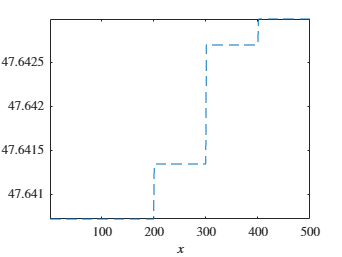

Undefined variable 'gc'.

% tc = cell(2,2);
% for r = 1:2
%     tc{r,1} = c{r,1};
%     for k = 2:10

%         tc{r,1} = [tc{r,1};
%                    c{r,k}];
%     end
%     t = tc{r,1}; tc{r,1} = t(ir(1:700),:);
%     tc{r,2} = t(ir(701:end),:);
% end
% tc

% tic; fprintf([num2str([2*col-1 toc]) ' s']);
% [toc/60 rem(toc, 60)]
% fprintf([num2str([2*col-1 toc]) ' s']);
% t = toc; fprintf([num2str([2*col-1 t]) ' s']);
% fprintf([num2str([2*col-1 toc]) ' s']);
% fprintf([num2str([2*col-1 toc]) ' s']);

nt = 2x2 cell array
    {700x6 table}    {300x6 table}
    {700x6 table}    {300x6 table}


% t = toc; fprintf([num2str([2*col-1 t]) ' s']);
% t = toc; fprintf([num2str([2*col-1 t]) ' s']);

9     7.6e-05 s

## Modelling precision N

tc = nrt;

ans =     0.0000    0.0025


for col = 1:2:10
    tc{1,col}.Ylatitude(:) = tc{1,...
    col}.Ylatitude(:)*10;
    tc{2,col}.Ylongitude(:) = tc{2,...
    col}.Ylongitude(:)*10;
end

1      11.1444 s
2      15.1009 s
3      5.0998 s
4      4.9877 s
5      2.8893 s
1      22.3014 s
2      7.7989 s
3      5.4753 s
4       7.963 s
5      5.2335 s


ans = '0: 5.2363s'

gs = 2x10 cell array
    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}
    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}    {1x1 RegressionGP}


% tc = nrt; te = 1; gt = gc;

load(ad, 'gtc') % /10 tc v

p = cell(2, l);
te = 10; gt = gtc;
for r = 1:2
    for co = 1:l/2
        e = 2*co; t = tc{r,e}; o = e-1;
        p{r, o} = predict(gt{r,o}, t(:, 1: ...
            end-1).Variables)/te;
        p{r, e} = predict(gt{r,e}, t(:, 1: ...
            end-1).Variables)/te;
    end
end
p

% k = p{1, 2}; k(1)

Unrecognized function or variable 'gtc'.

k = p{2, 1}; k(1)

## dikm

d1km = cell(1, l);

## N/10

d = d1km; t = 1;

ans = -122.1387

for co = 1:l
    la = p{1, co}; lo = p{2, co};
    e = 2*ceil(co/2); k = la;
    for i = 1:length(la)
        [k(i), ~] = lldistkm(...
            [tc{1,e}.Ylatitude(i...
            ) tc{2,e}.Ylongitude(i...
            )], [la(i) lo(i)]/t);
    end
    d{co} = k*1000;
end
d
k = d{1}; k(1)

i = 5; e = 2;

d = 1x10 cell array
    {100x1 double}    {100x1 double}    {200x1 double}    {200x1 double}    {300x1 double}    {300x1 double}    {400x1 double}    {400x1 double}    {500x1 double}    {500x1 double}


[tc{1,e}.Ylatitude(i...

ans = 5.0711

            ) tc{2,e}.Ylongitude(i...
            ) la(i) lo(i)]

% fiv = 1;
for i = 1
    % :l/2

ans =    47.6421 -122.1387   47.6464 -122.1426


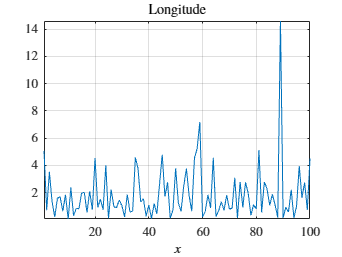

    figure;
    % r = 2; co = 2; t = nrt{r,co};
    plot(k);
    % plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe();
    % hold on;
    % plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
    %     ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    % hold off;
    grid on; % xline(I)
    % legend({'data','predictions1' ...
     % ,'p2' ...
     % }, ...
     % 'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

## nt

co = 1; nt{1,co}.Ylatitude(:) = nt{1,...
co}.Ylatitude(:)*10;
nt{2,co}.Ylongitude(:) = nt{2,...
co}.Ylongitude(:)*10;

Elapsed time is 0.471125 seconds.


gn = 2x2 cell array
    {1x1 RegressionGP}    {0x0 double}
    {0x0 double      }    {0x0 double}


% load(ad, 'gn')
% t = nt{1,1}; % gn, nt
% t(1:3, end).Variables
% t = nt{r,1}; % gn, nt
% t(1:3, end).Variables
% pt(1,1,1)

pt = zeros(300,2,10); nt = nrt; % tr ts
gn = gc;
for col = 2:2:10
    for r = 1:2
        for co = 1:10 % mdls
            t = nt{r,col}; % gn, nt
            pt(:,r, co) = predict(gn{r,co}, t(:,...
                1:end-1).Variables); % has x 10
        end
    end
end

## /10

for co = 1:2
    for i = 1:300 % pt, gn
        [d1km(i, co), ~] = ...
            lldistkm(...
            [nt{1,2}.Ylatitude(i ...
            ) nt{2,2}.Ylongitude(i ...
            )], [pt(i,1,co) pt(i,2,co)]/10);
    end
end
d1km = d1km*1000;

load(ad, 'gs')

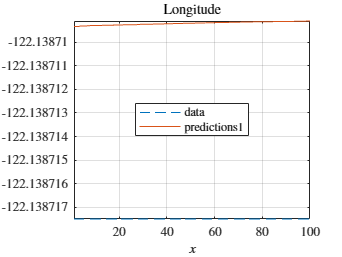

p = zeros(300,2,2);
for r = 1:2
    for co = 1:2
        t = nrt{r,2};
        p(:,r, co) = predict(gs{r,co},t(:, 1: ...
            end-1).Variables);
    end
end

## Normal

ndk = d1km;
for co = 1:2
    for i = 1:300
        [ndk(i, co), ~] = ...
            lldistkm([nrt{1,2}.Ylatitude(i...
            ) nrt{2,2}.Ylongitude(i...
            )], [p(i,1,co) p(i,2,co)]);
    end
end
ndk = ndk*1000;

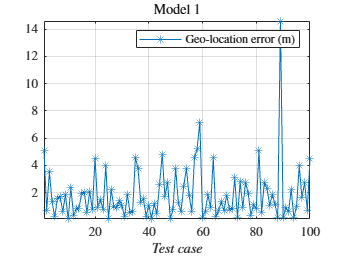

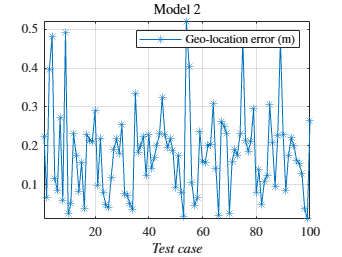

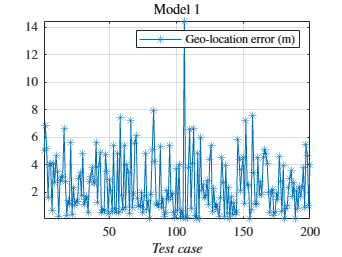

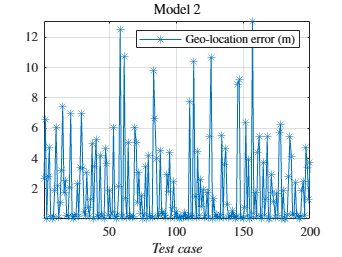

fiv = 1;

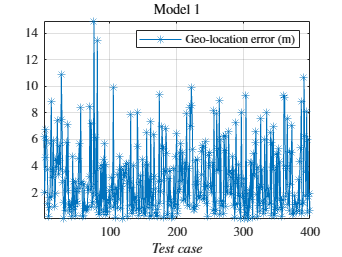

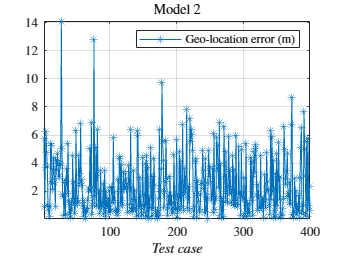

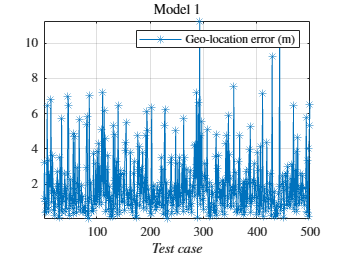

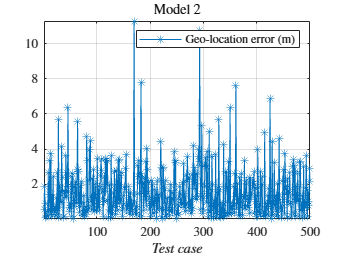

for i = 1
    % :l/2
    figure;
    r = 2; co = 2; t = nrt{r,co};
    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...
     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

fiv = 1;

ans =      1     1     2     2     3     3     4     4     5     5
     0     1     1     2     2     3     3     4     4     5


for i = 1
    % :l/2

ans =      1     0     1     0     1     0     1     0     1     0
     0     2     2     4     4     6     6     8     8    10
     1     2     2     3     3     4     4     5     5     6


    figure;
    r = 2; t = nrt{r,co};

ans =      0     1     1     2     2     3     3     4     4     5
     1     2     1     2     1     2     1     2     1     2


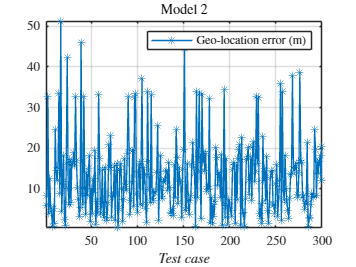

    plot(sort(t(:, end).Variables/fiv),'--');
    xlabel('$x$','interpreter','latex'); axis tight
    axe(); hold on;
    plot(sort(predict(gc{r,co},t(:, 1:end-1 ...
        ).Variables)/fiv))
    % plot(predict(gt{r,co},t(:, 1:end-1 ...
    % ).Variables)/f)
    hold off; grid on; % xline(I)
    legend({'data','predictions1' ...
     % ,'p2' ...
     }, ...

     'Location','Best','interpreter','latex')
    title('Longitude','interpreter','latex')
end

## Without x/10

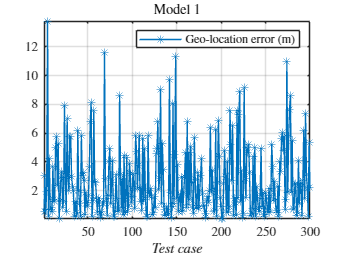

for i = 1:4%l
    figure;
    ndk = d{i}; plot(ndk(:),'-*'); axis tight
    xlabel('$Test$ $case$','interpreter','latex')

    legend('Geo-location error (m)', ...
    'interpreter','latex'); axe(); grid on
    % print(fig,'DistG','-djpeg')
    title(['Model ' num2str(rem(i,2) + ~rem( ...
        i,2)*2)], 'interpreter','latex')
end

## Without x/10

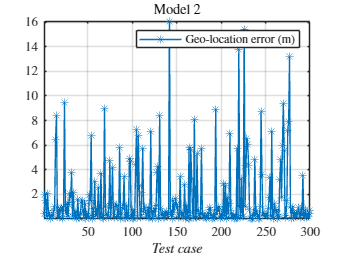

for i = 7:10%l

    figure;
    ndk = d{i}; plot(ndk(:),'-*'); axis tight
    xlabel('$Test$ $case$','interpreter','latex')
    legend('Geo-location error (m)', ...
    'interpreter','latex'); axe(); grid on
    % print(fig,'DistG','-djpeg')
    title(['Model ' num2str(rem(i,2) + ~rem( ...
        i,2)*2)], 'interpreter','latex')

ans =     0.0064   16.0930


end

i = 1:10; [i-floor(i/2); floor(i/2)]

[rem(i,2);i-rem(i,2); floor((1+i/2))]

[fix(i/2);rem(i,2) + ~rem(i,2)*2]

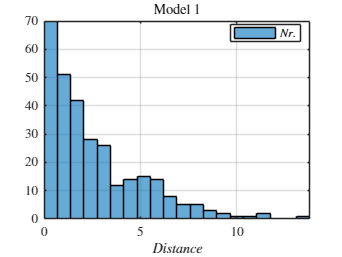

figure; plot(ndk(:, 2),'-*');
axis tight; axe(); grid on

xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex')
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')
% print(fig,'DistG','-djpeg')
title('Model 2','interpreter','latex')

## No noise

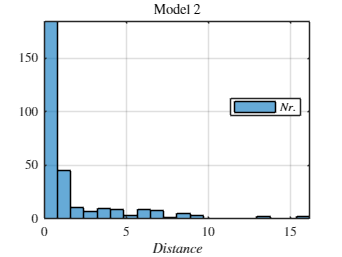

figure; plot(d(:, 1),'-*'); axis tight
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% print(fig,'DistG','-djpeg')
title('Model 1','interpreter','latex')

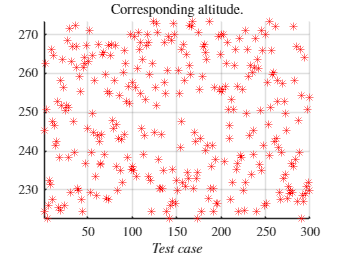

figure; plot(d(:, 2),'-*'); axis tight
% title('Model 1','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); grid on; axe()
% print(fig,'DistG','-djpeg')
title('Model 2','interpreter','latex')

fid = fopen('cv/10c/n.txt','w');
for i=1:300
    fprintf(fid, ['(' num2str(i) ',' num2str( ...
        d(i, 2)) ')']);
end
fclose(fid);

ans =   222.5352  273.4859


[min(d(:, 2)) max(d(:, 2))]

% print(fig,'Ca','-djpeg')
figure; h = histogram(d(:, 1),20);
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')

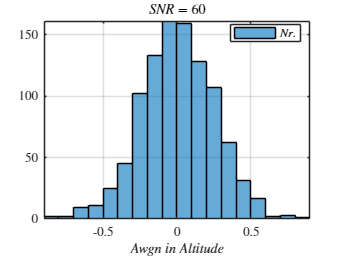

% print(fig,'Ca','-djpeg')
figure;

% h = ...
    histogram(d(:, 2),20);
title('Model 2','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
grid on
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex');
axis tight

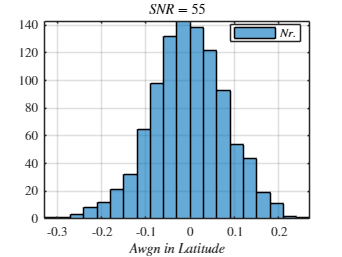

figure;
scatter(1:300, tc{1,2}.Altitude(:),'r*');
xlabel('$Test$ $case$','interpreter','latex');axe()
% ylabel('')

grid on; title('Corresponding altitude.', ...
'interpreter','latex'); axis tight

x = (1:300)';
y = [tc{1,2}.Altitude(:)];
class = char('a'*ones(300,1));
writetable(table(x, y, class),'cv/10c/s.txt', ...
    'Delimiter',' ');
[min(y) max(y)]

## Overall

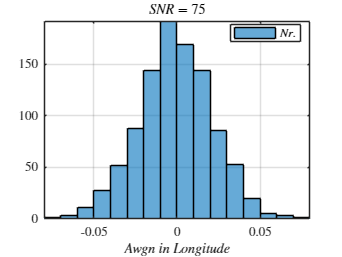

% sh = 60;
figure;
% h = ...

    histogram(kh - n(:,1).Variables); axis tight
xlabel('\it Awgn in Altitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex');
title(['$SNR = $',num2str(sh)], ...
    'interpreter','latex'); axe()
% '$\frac{d}{dx}sin(x)$';
% print(fig,'Ha','-djpeg')

% snr = 60;
figure;

ans =    100   580


Drone data, output: Latitude
8 of 1000 rows, 3 of 6 cols

ans = 8x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.67      47.695      -122.13      236       190       47.643  
     224.89      47.581      -122.11      236       191       47.643  
     223.87      47.604      -122.12      236       191       47.643  
     224.95      47.581      -122.15      236       191       47.643  
     225.49      47.686      -122.14      236       192       47.643  
     225.76      47.572      -122.12      236       192       47.643  
     226.37      47.547      -122.14      236       192       47.643  
     227.13      47.684      -122.12      236       193       47.643  


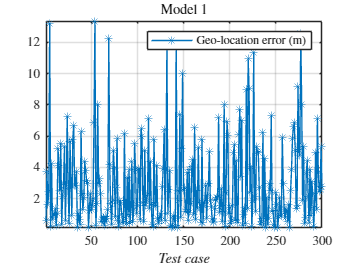

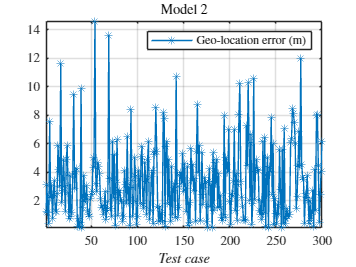

% h = ...
    histogram(ka - n(:,2).Variables); axis tight
xlabel('\it Awgn in Latitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter','latex'); % 'northwest'
title(['$SNR = $',num2str(snr)], ...
    'interpreter','latex'); axe()
% print(fig,'Hla','-djpeg')

% so = snr+20;%-10;
figure;
% h = ...
    histogram(o - n(:,3).Variables); axis tight
xlabel('\it Awgn in Longitude','interpreter', ...
    'latex'); grid on
legend({'$Nr.$'}, 'Location','Best', ...
    'interpreter', 'latex');
title(['$SNR = $',num2str(so)], ...
    'interpreter','latex'); axe()
% print(fig,'Ho','-djpeg')

## 
$$Bins$$


fid = fopen('cv/10c/n.txt','w');
for i=1:h.NumBins
    fprintf(fid, ['(' num2str(h.BinEdges(i) ...
        ) ',' num2str(h.Values(i)) ')']);
end
fprintf(fid, ['(' num2str(h.BinEdges(i+1)) ',0)']);
fclose(fid);
[max(h.Values) h.BinEdges(end)]

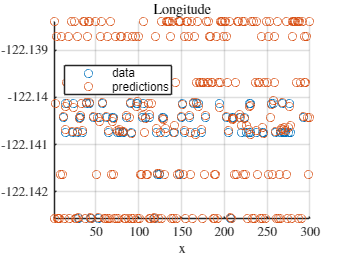

fprintf(['Drone data, output: Latitude\n' ...

    '8 of ' num2str(length(n(:,1).Variables) ...
    ) ' rows, 3 of 6 cols']); n(1:8,:)

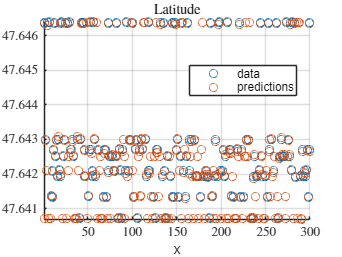

figure; plot(d1km(:, 1),'-*'); axis tight
title('Model 1','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); grid on; axe()
% ylabel('Geo-location error (in meters)', ...
% 'interpreter','latex')

% print(fig,'DistG','-djpeg')

figure; plot(d1km(:, 2),'-*'); axis tight
title('Model 2','interpreter','latex')
xlabel('$Test$ $case$','interpreter','latex')
legend('Geo-location error (m)', ...
'interpreter','latex'); axe(); grid on
% print(fig,'DistG','-djpeg')

fid = fopen('cv/10c/n.txt','w');

ans =  -122.1426 -122.1384


for i=1:300
    fprintf(fid, ['(' num2str(i) ',' num2str( ...

ans =    47.6407   47.6464


        d1km(i, 1)) ')']);
end
fclose(fid);
[min(y) max(y)]

m =     0.1261    0.0669


i =     35   242


M =    13.3737   14.6186


I =     54    54


ans = 4x2 cell array
    {[ 0.1261]}    {[ 35]}
    {[13.3737]}    {[ 54]}
    {[ 0.0669]}    {[242]}
    {[14.6186]}    {[ 54]}


open('cv/10c/n.txt')

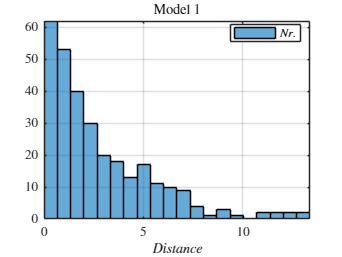

figure(); t = nt{2, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x','interpreter','latex');
% ylabel('y');
hold on;

scatter(1:300, pt(:,2,2)/10); hold off; grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude','interpreter','latex'); axe()

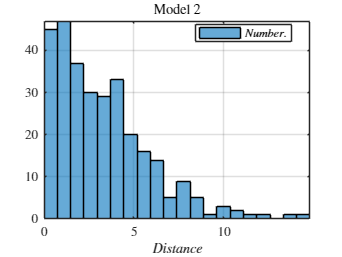

figure(); t = nt{1, 2}; scatter(1:300, t(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; xlabel('x');
% ylabel('y');
hold on;
scatter(1:300, pt(:,1,2)/10); hold off; grid on

legend({'data','predictions'}, ...
    'Location','Best');
title('Latitude','interpreter','latex'); axe()

ans = '14.06'

x = [1:300 1:300]';
y = [t(:, end).Variables; pt(:,2,2)/10];
class = char(['a'*ones(300,1);'b'*ones(300,1)]);
writetable(table(x, y, class),'cv/10c/s.txt', ...
    'Delimiter',' ');

y = [t(:, end).Variables; pt(:,1,2)/10];
writetable(table(x, y, class),'cv/10c/s.txt', ...
    'Delimiter',' ');

[min(y) max(y)]

[m, i] = min(d1km);
[M, I] = max(d1km); {m(1), M(1), m(2), M(2);
                     i(1), I(1), i(2), I(2)}'

% print(fig,'Ca','-djpeg')
figure;
% h = ...
    histogram(d1km(:, 1),20);
title('Model 1','interpreter','latex')
xlabel('$Distance$','interpreter','latex'); axe()
legend({'$Nr.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; grid on
% title(['$SNR = $',num2str(so)], ...
% 'interpreter','latex')

figure;
% h = ...
    histogram(d1km(:, 2),20);
title('Model 2','interpreter','latex'); grid on
xlabel('$Distance$','interpreter','latex');
% legend({'$Nr.$'}, 'Location', 'Best', ...
legend({'$Number.$'}, 'Location', 'Best', ...
'interpreter', 'latex'); axis tight; axe()
% print(fig,'Ca','-djpeg')
% print('cv/10c/Ca','-depsc')

num2str(h.BinEdges(i))

fid = fopen('cv/10c/n.txt','w');
for i=1:h.NumBins
    fprintf(fid, ['(' num2str(h.BinEdges(i) ...
        ) ',' num2str(h.Values(i)) ')']);
end
fclose(fid);

## M2

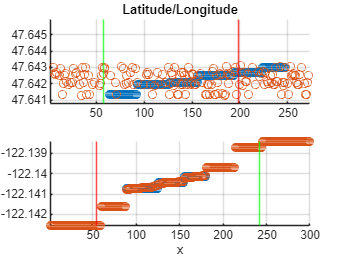

ans = 0.0669

figure(); subplot(2,1,1); t = nt{1, 2};
[s1, i1] = sort(t(:, end).Variables);
scatter(1:300, s1);
% scatter(1:300, sort(t(:, end).Variables));
% scatter(1:300, t(:, end).Variables);
% plot(tlts(:, ...
%     end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight; hold on; [sd, id] = sort(d1km(:,2));
[s, in] = sort(pt(:,1,2)/10);
tt = pt(:,1,2)/10;

% scatter(1:300, s); hold off;
% scatter(1:300, tt(i1)); hold off;
% scatter(1:300, pt(:,1,2)/10); hold off;
scatter(i1, pt(:,1,2)/10); hold off;
grid on; title('Latitude/Longitude');
% legend({'dataA','predA'}, ...
%     'Location','Best');
m2 = [find(I(2)==i1); find(i(2)==i1)];
% m2 = [find(I(2)==in); find(i(2)==in)];
% m2 = [find(I(2)==id); find(i(2)==id)];
% xline(id(1), 'g'); xline(id(end), 'r')
xline(m2(2), 'g'); xline(m2(1), 'r')

subplot(2,1,2);
 t = nt{2, 2}; scatter(1:300, sort(t(:, ...
    end).Variables)); axis tight; xlabel('x')
hold on;
scatter(1:300, sort(pt(:,2,2)/10)); hold off;
grid on
% legend({'dataL','predL'}, ...
%     'Location','Best');
% xline(m2(2), 'g'); xline(m2(1), 'r')
xline(id(1), 'g'); xline(id(end), 'r')

d1km(id(1),2)

function axe()
    axes = gca;
    axes.XAxis.TickLabelInterpreter = 'latex';
    axes.YAxis.TickLabelInterpreter = 'latex';
end